% I ran this section individually each time then ran the appropriate
% section below so that VlX and VphX wouldn't be overwritten
arduino = serial("/dev/cu.usbmodem141301",'BaudRate',9600);
pause(1)
fopen(arduino);
writedata=uint16(500); %0x01F4
VR = [0];

for i=1:202
    fwrite(arduino,writedata,'uint16')
    pause(.5)
    readData = fscanf(arduino,'%f')
    VR = [VR readData]; 
end

fclose(arduino);

% for white LED
VlW = VR(2:2:end) %1kΩ resistor voltage
VphW = VR(3:2:end) %10kΩ resistor voltage

% for red LED
VlR = VR(2:2:end) %1kΩ resistor voltage
VphR = VR(3:2:end) %10kΩ resistor voltage

% for blue LED
VlB = VR(2:2:end) %1kΩ resistor voltage
VphB = VR(3:2:end) %10kΩ resistor voltage

% for green LED
VlG = VR(2:2:end) %1kΩ resistor voltage
VphG = VR(3:2:end) %10kΩ resistor voltage

% for yellow LED
VlY = VR(2:2:end) %1kΩ resistor voltage
VphY = VR(3:2:end) %10kΩ resistor voltage

% backing up to excel files
writematrix(VlW,'VlW.xlsx')
writematrix(VphW,'VphW.xlsx')

writematrix(VlR,'VlR.xlsx')
writematrix(VphR,'VphR.xlsx')

writematrix(VlB,'VlB.xlsx')
writematrix(VphB,'VphB.xlsx')

writematrix(VlG,'VlG.xlsx')
writematrix(VphG,'VphG.xlsx')

writematrix(VlY,'VlY.xlsx')
writematrix(VphY,'VphY.xlsx')

% reading excel files
VlW = xlsread('VlW.xlsx');
VphW = xlsread('VphW.xlsx');

VlR = xlsread('VlR.xlsx');
VphR = xlsread('VphR.xlsx')

VphR =          0    0.1800    0.3800    0.5700    0.7400    0.8900    1.0300    1.1500    1.2600    1.3600    1.4600    1.5500    1.6300    1.7100    1.7700    1.8400    1.9100    1.9700    2.0300    2.0800    2.1300    2.1900    2.2300    2.2700    2.3300    2.3600    2.4000    2.4500    2.4800    2.5100    2.5500    2.5800    2.6200    2.6500    2.6800    2.7100    2.7400    2.7600    2.7900    2.8200    2.8400    2.8600    2.8900    2.9000    2.9300    2.9500    2.9700    3.0000    3.0200    3.0300
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN  


VlB = xlsread('VlB.xlsx');
VphB = xlsread('VphB.xlsx');

VlG = xlsread('VlG.xlsx');
VphG = xlsread('VphG.xlsx');

VlY = xlsread('VlY.xlsx');
VphY = xlsread('VphY.xlsx');

%CALCULATIONS
PWM = 0:100;
DCeff = (PWM/100)*5;

%white LED
PhotocellResistance_white = (5*10000./VphW)-10000;
PhotocellCurrent_white = 5./(10000+PhotocellResistance_white);
PhotocellVoltage_white = 5 - VphW;
LEDResistance_white = 1000-((1000.*DCeff)./VlW);
LEDCurrent_white = DCeff./(1000.+LEDResistance_white);

%red LED
PhotocellResistance_red = (5*10000./VphR)-10000;
PhotocellCurrent_red = 5./(10000+PhotocellResistance_red);
PhotocellVoltage_red = 5 - VphR;
LEDResistance_red = 1000-((1000.*DCeff)./VlR);
LEDCurrent_red = DCeff./(1000.+LEDResistance_red);

%blue LED
PhotocellResistance_blue = (5*10000./VphB)-10000;
PhotocellCurrent_blue = 5./(10000+PhotocellResistance_blue);
PhotocellVoltage_blue = 5 - VphB;
LEDResistance_blue = 1000-((1000.*DCeff)./VlB);
LEDCurrent_blue = DCeff./(1000.+LEDResistance_blue);

%green LED
PhotocellResistance_green = (5*10000./VphG)-10000;
PhotocellCurrent_green = 5./(10000+PhotocellResistance_green);
PhotocellVoltage_green = 5 - VphG;
LEDResistance_green = 1000-((1000.*DCeff)./VlG);
LEDCurrent_green = DCeff./(1000.+LEDResistance_green);

%yellow LED
PhotocellResistance_yellow = (5*10000./VphY)-10000;
PhotocellCurrent_yellow = 5./(10000+PhotocellResistance_yellow);
PhotocellVoltage_yellow = 5 - VphY;
LEDResistance_yellow = 1000-((1000.*DCeff)./VlY);
LEDCurrent_yellow = DCeff./(1000.+LEDResistance_yellow);


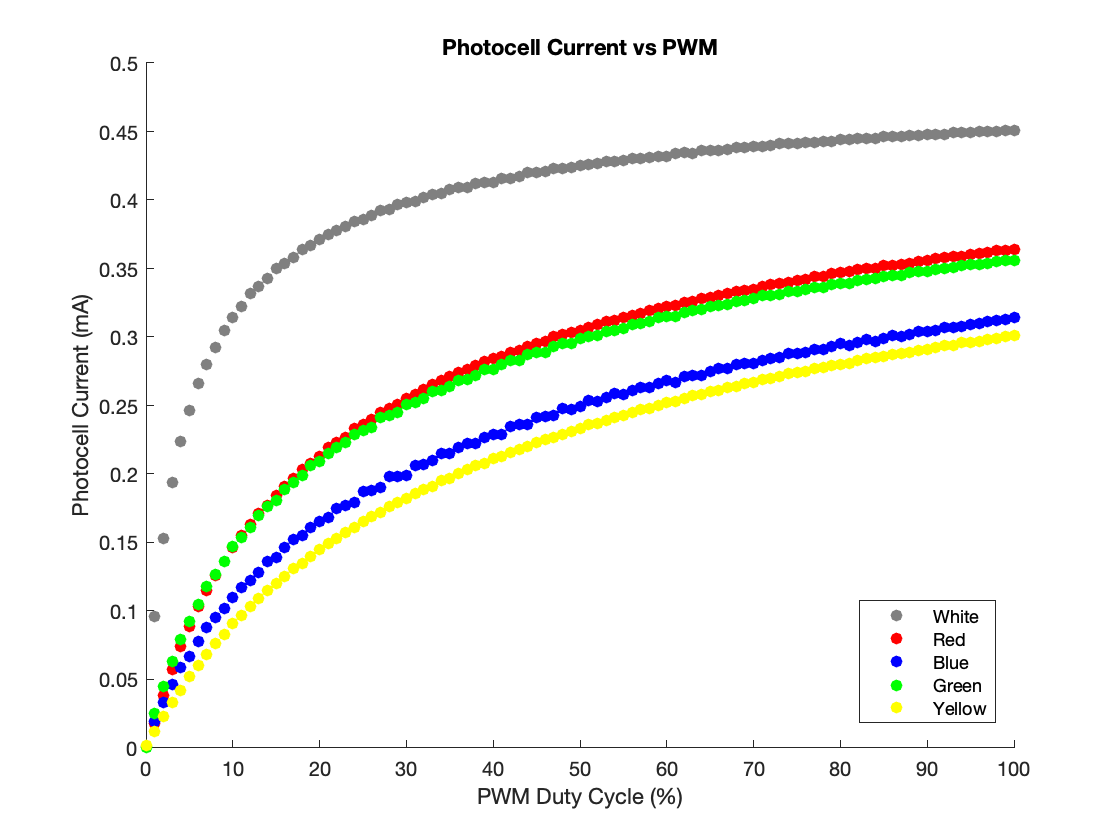

%Photocell Current vs Duty Cycle Plots
figure()
scatter(PWM, PhotocellCurrent_white*1000,[],[0.5 0.5 0.5],'filled')
title('Photocell Current vs PWM')
xlabel('PWM Duty Cycle (%)')
ylabel('Photocell Current (mA)')
hold on
scatter(PWM, PhotocellCurrent_red*1000, 'r', 'filled')
scatter(PWM, PhotocellCurrent_blue*1000, 'b', 'filled')
scatter(PWM, PhotocellCurrent_green*1000, 'g', 'filled')
scatter(PWM, PhotocellCurrent_yellow*1000, 'y', 'filled')
legend('White','Red','Blue','Green','Yellow', 'Location','best')
hold off

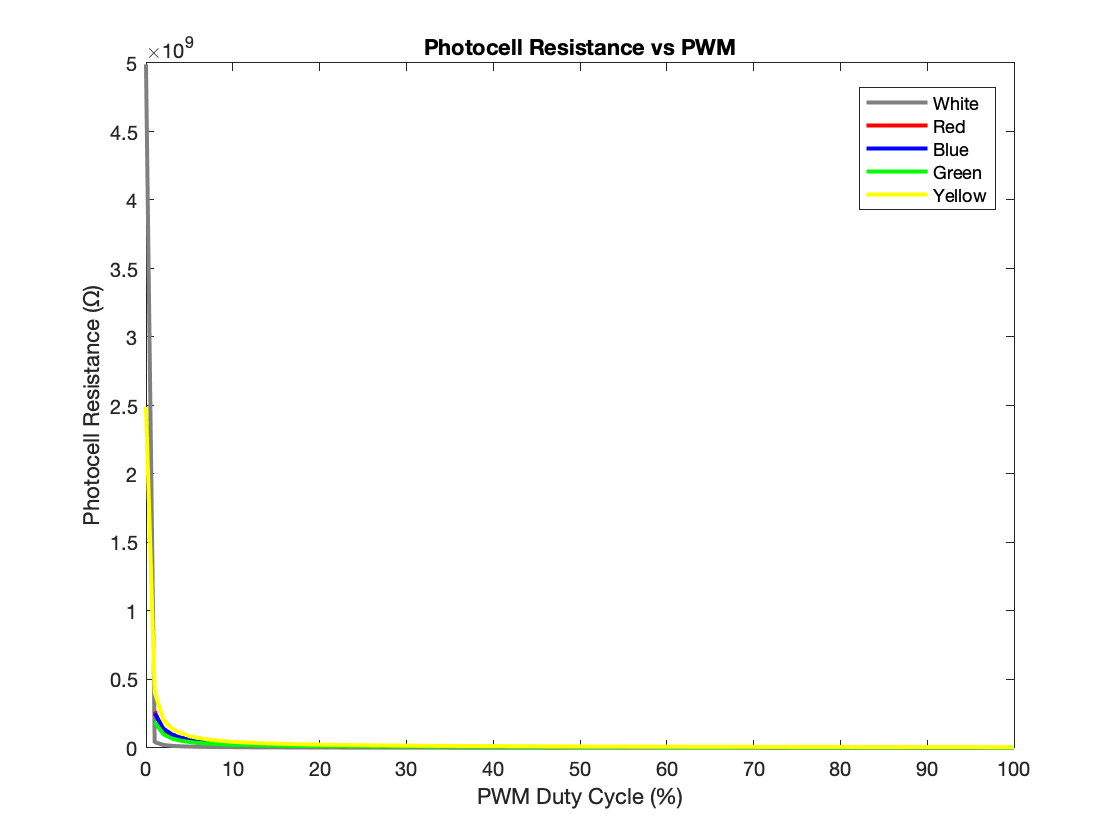


%Photocell Resistance vs Duty Cycle Plots 
plot(PWM, PhotocellResistance_white*1000, 'color',[0.5 0.5 0.5],'LineWidth',2)
title('Photocell Resistance vs PWM')
xlabel('PWM Duty Cycle (%)')
ylabel('Photocell Resistance (Ω)')
hold on
plot(PWM, PhotocellResistance_red*1000, 'r','LineWidth',2)
plot(PWM, PhotocellResistance_blue*1000, 'b','LineWidth',2)
plot(PWM, PhotocellResistance_green*1000, 'g','LineWidth',2)
plot(PWM, PhotocellResistance_yellow*1000, 'y','LineWidth',2)
legend('White','Red','Blue','Green','Yellow', 'Location','best')
hold off

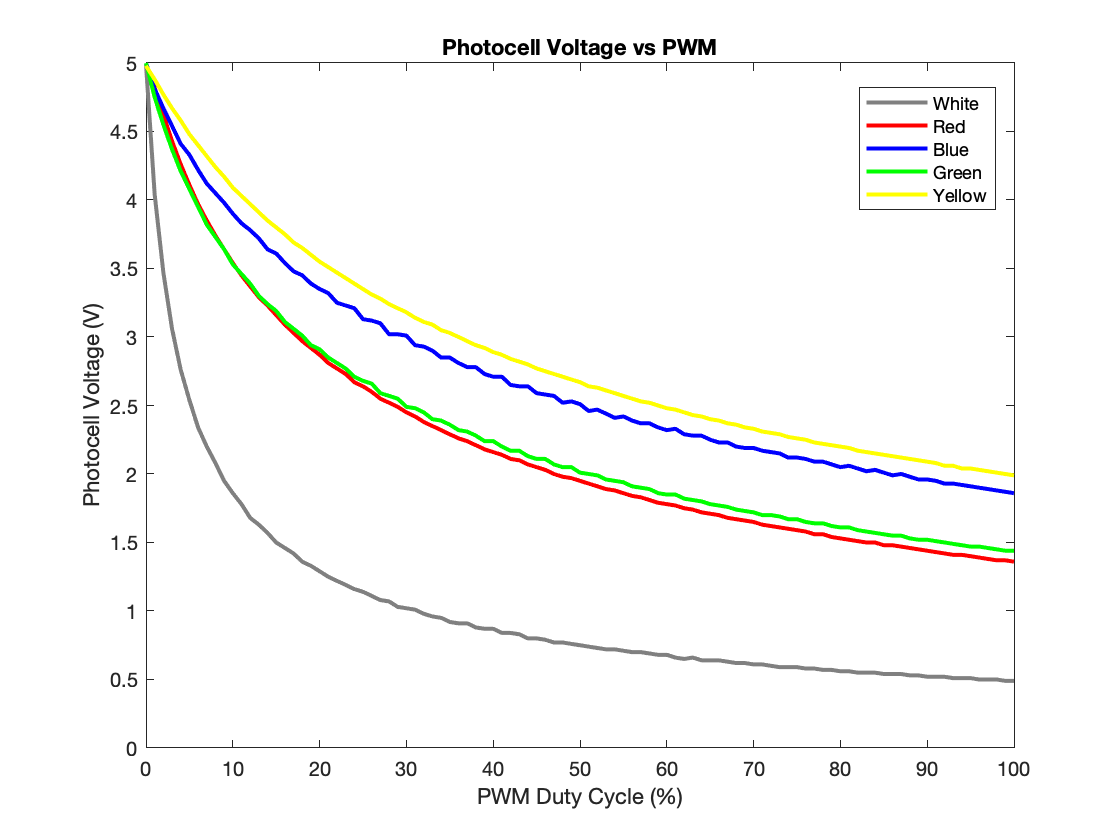


%Photocell Voltage vs Duty Cycle Plots 
plot(PWM, PhotocellVoltage_white, 'color',[0.5 0.5 0.5],'LineWidth',2)
title('Photocell Voltage vs PWM')
xlabel('PWM Duty Cycle (%)')
ylabel('Photocell Voltage (V)')
hold on
plot(PWM, PhotocellVoltage_red, 'r','LineWidth',2)
plot(PWM, PhotocellVoltage_blue, 'b','LineWidth',2)
plot(PWM, PhotocellVoltage_green, 'g','LineWidth',2)
plot(PWM, PhotocellVoltage_yellow, 'y','LineWidth',2)
legend('White','Red','Blue','Green','Yellow', 'Location','best')
hold off

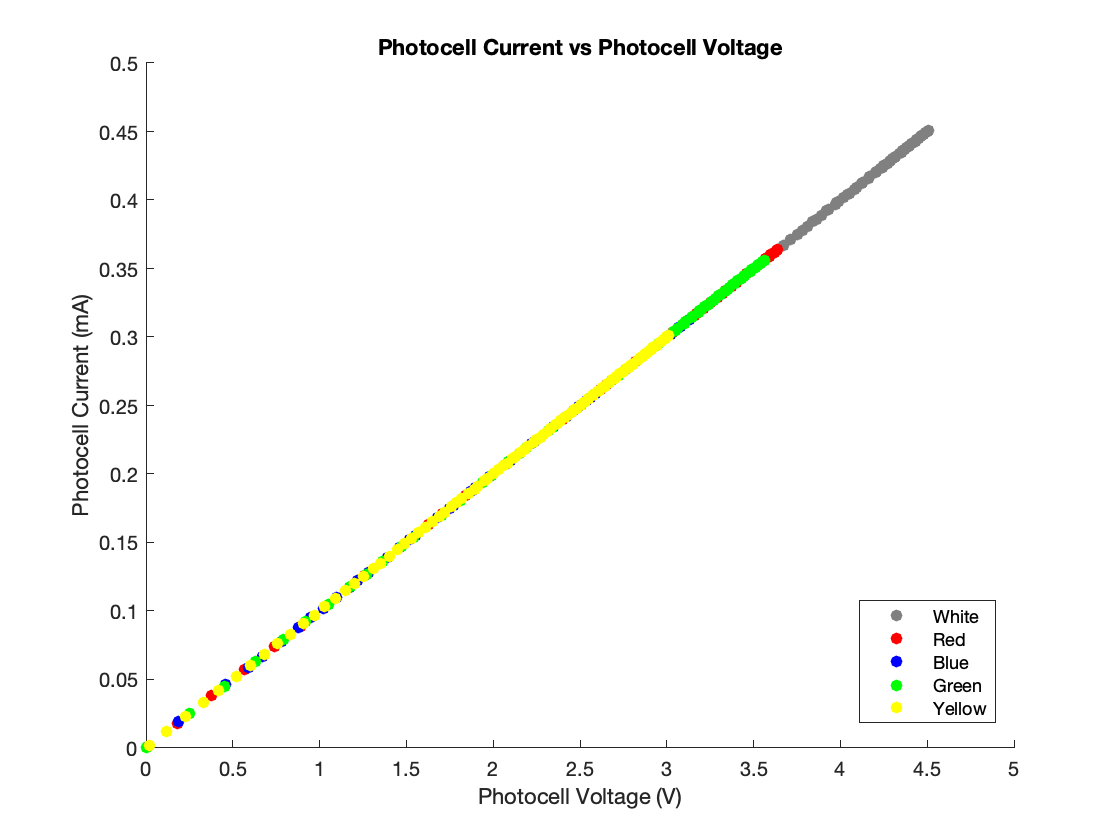


%Photocell Current vs Photocell Voltage
scatter(VphW, PhotocellCurrent_white*1000, [],[0.5 0.5 0.5],'filled')
title('Photocell Current vs Photocell Voltage')
xlabel('Photocell Voltage (V)')
ylabel('Photocell Current (mA)')
hold on
scatter(VphR, PhotocellCurrent_red*1000, 'r', 'filled')
scatter(VphB, PhotocellCurrent_blue*1000, 'b', 'filled')
scatter(VphG, PhotocellCurrent_green*1000, 'g', 'filled')
scatter(VphY, PhotocellCurrent_yellow*1000, 'y', 'filled')
legend('White','Red','Blue','Green','Yellow', 'Location','best')
hold off

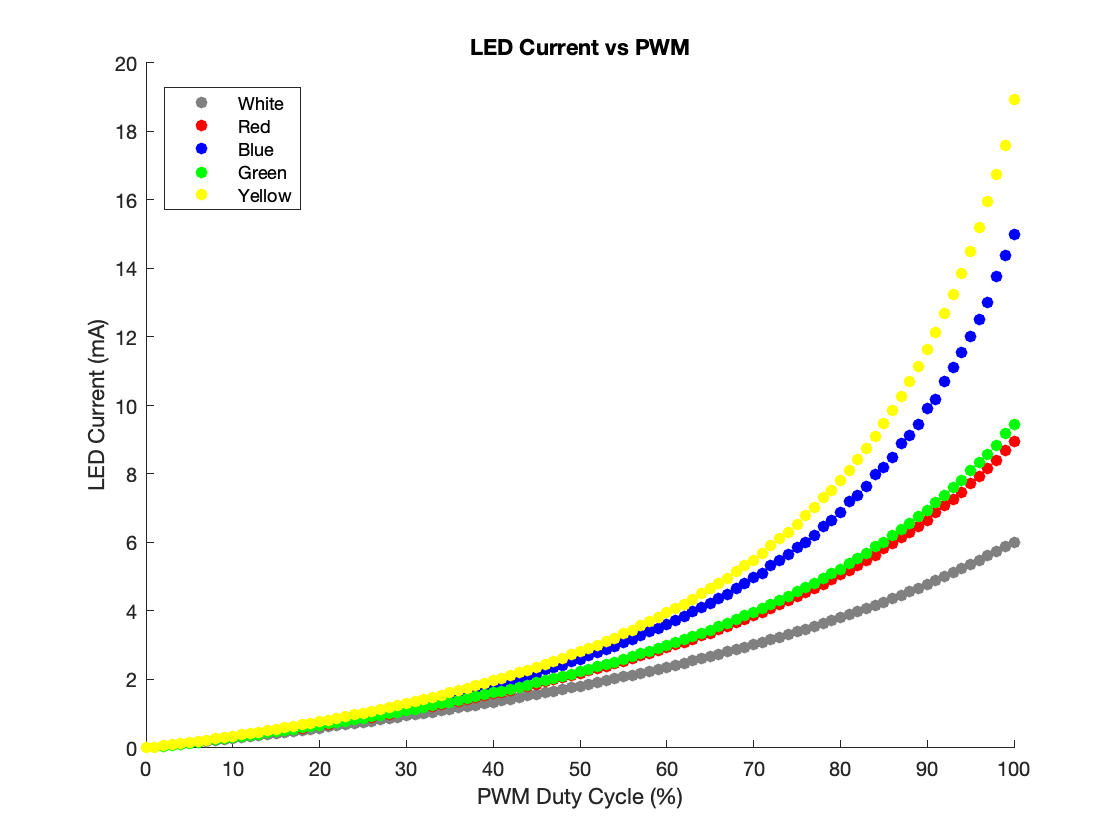


%LED Current vs Duty Cycle Plots 
scatter(PWM, LEDCurrent_white*1000,[],[0.5 0.5 0.5],'filled')
title('LED Current vs PWM')
xlabel('PWM Duty Cycle (%)')
ylabel('LED Current (mA)')
hold on
scatter(PWM, LEDCurrent_red*1000, 'r', 'filled')
scatter(PWM, LEDCurrent_blue*1000, 'b', 'filled')
scatter(PWM, LEDCurrent_green*1000, 'g', 'filled')
scatter(PWM, LEDCurrent_yellow*1000, 'y', 'filled')
legend('White','Red','Blue','Green','Yellow', 'Location','best')
hold off

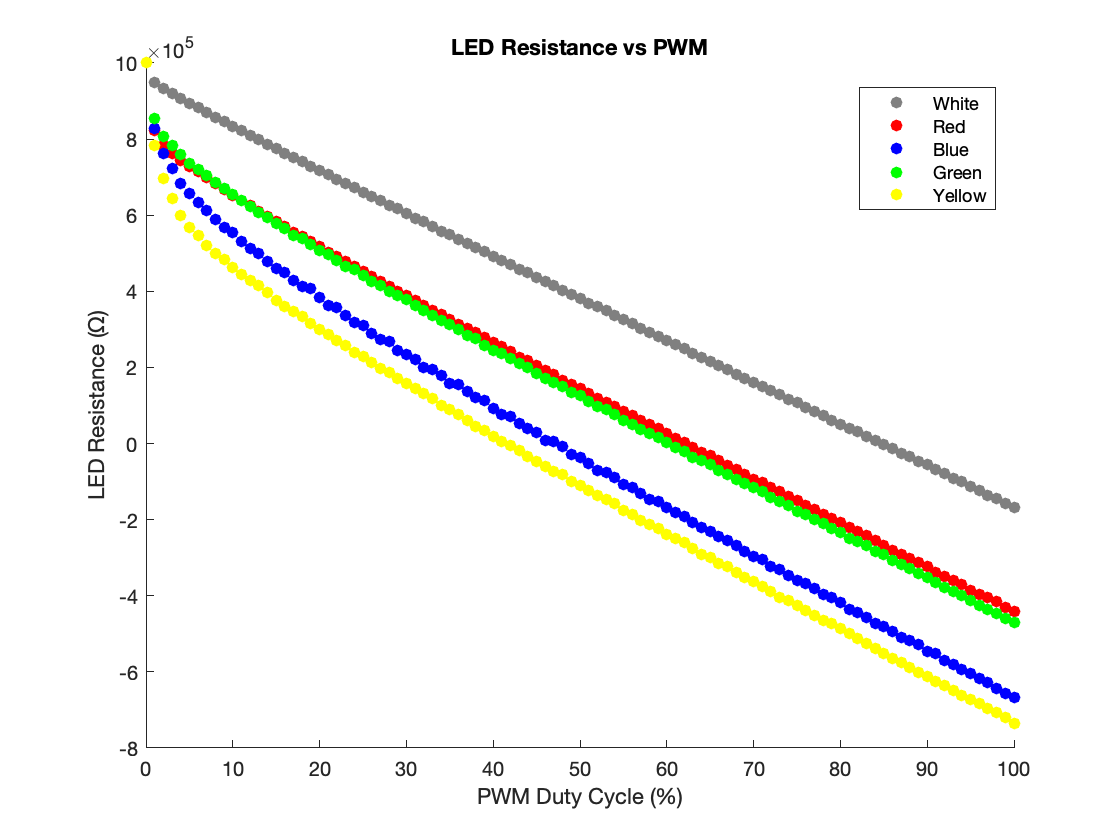


%LED Resistance vs Duty Cycle Plots 
scatter(PWM, LEDResistance_white*1000,[],[0.5 0.5 0.5],'filled')
title('LED Resistance vs PWM')
xlabel('PWM Duty Cycle (%)')
ylabel('LED Resistance (Ω)')
hold on
scatter(PWM, LEDResistance_red*1000, 'r', 'filled')
scatter(PWM, LEDResistance_blue*1000, 'b', 'filled')
scatter(PWM, LEDResistance_green*1000, 'g', 'filled')
scatter(PWM, LEDResistance_yellow*1000, 'y', 'filled')
legend('White','Red','Blue','Green','Yellow', 'Location','best')
hold off

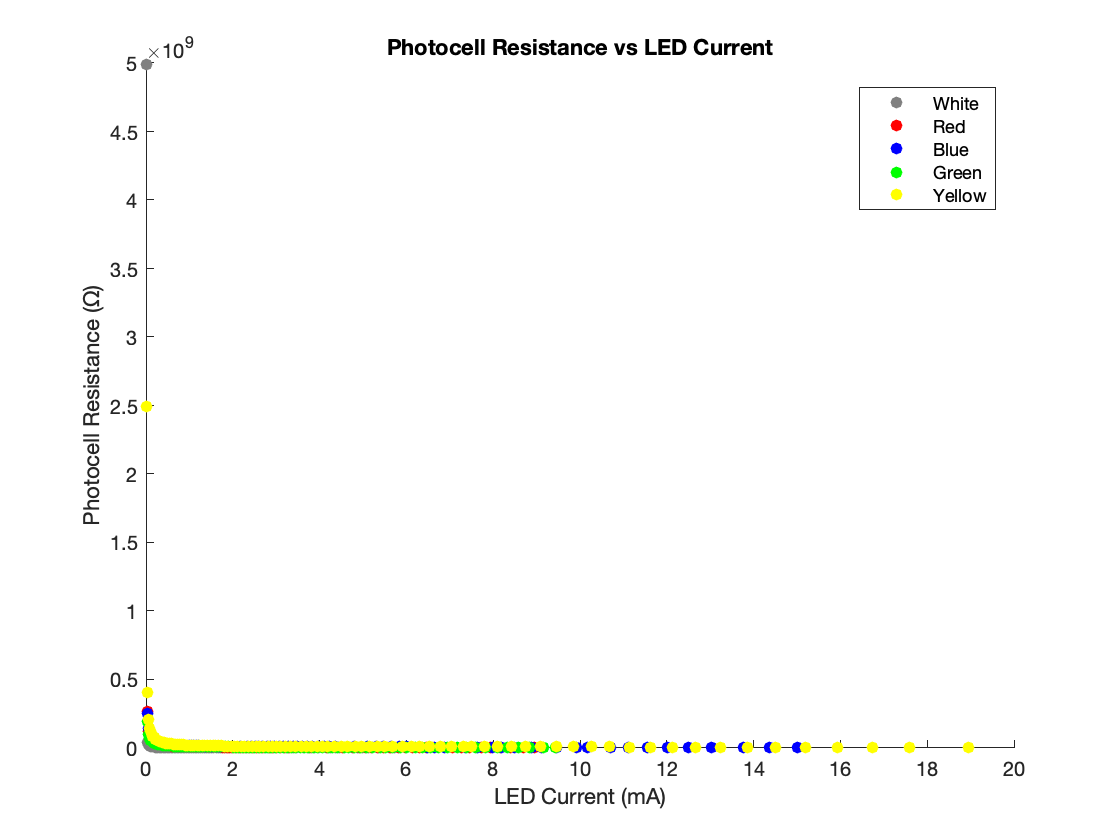


%Photocell Resistance vs LED Current Plots
scatter(LEDCurrent_white*1000, PhotocellResistance_white*1000, [],[0.5 0.5 0.5],'filled')
title('Photocell Resistance vs LED Current')
xlabel('LED Current (mA)')
ylabel('Photocell Resistance (Ω)')
hold on
scatter(LEDCurrent_red*1000, PhotocellResistance_red*1000, 'r', 'filled')
scatter(LEDCurrent_blue*1000, PhotocellResistance_blue*1000, 'b', 'filled')
scatter(LEDCurrent_green*1000, PhotocellResistance_green*1000, 'g', 'filled')
scatter(LEDCurrent_yellow*1000, PhotocellResistance_yellow*1000, 'y', 'filled')
legend('White','Red','Blue','Green','Yellow', 'Location','best')
hold off